**Feedforward propagation and prediction**

3 Layers Neural Network with a set of network parameters $(\Theta^{(1)},\Theta^{(2)})$ already trained; 25 units in the second layer and 10 output units (corresponding to the 10 digit classes).

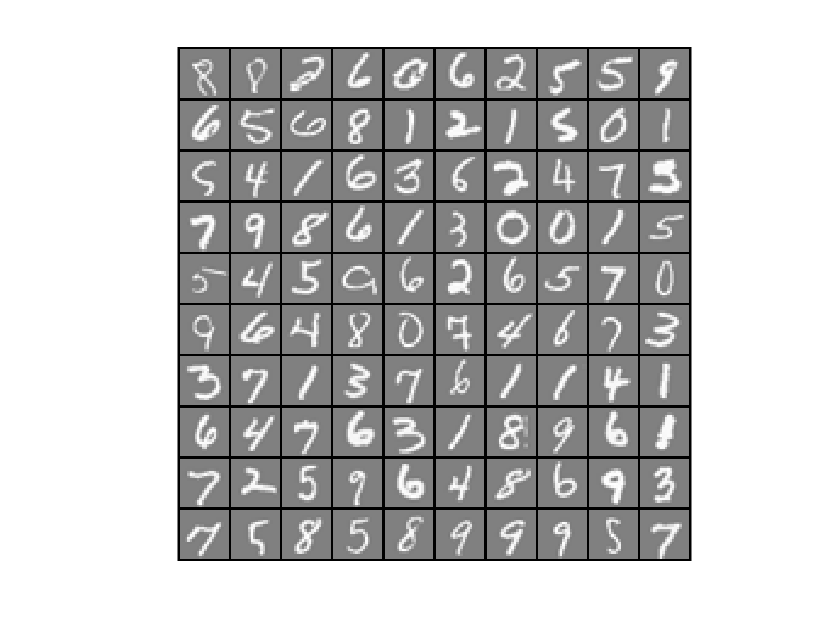

load('ex3data1.mat');
m = size(X, 1);
% Randomly select 100 data points to display
sel = randperm(size(X, 1));
sel = sel(1:100);
displayData(X(sel, :));

% Load saved matrices from file
load('ex3weights.mat'); 
% Theta1 has size 25 x 401
% Theta2 has size 10 x 26

**Feedforward propagation and prediction and accuracy**

pred = predict(Theta1, Theta2, X);
fprintf('\nTraining Set Accuracy: %f\n', mean(double(pred == y)) * 100);


Training Set Accuracy: 97.520000


Make prediction of random choice

%  Randomly permute examples
%rp = randi(m);
% Display 
%displayData(X(rp, :)); 
% Predict
%pred = predict(Theta1, Theta2, X(rp,:));
%fprintf('\nNeural Network Prediction: %d (digit %d)\n', pred, mod(pred, 10));
% Trial from reading img
[X_try Y_try] = IMG('Nu4.jpg')
[X_try, mu, sigma] = featureNormalize(X_try);
%X_try = X(1500,:);
imshow(reshape(X_try,[20 20]))
pred_try = predict(Theta1, Theta2, X_try);
fprintf('\nNeural Network Prediction: %d (digit %d)\n', pred_try, mod(pred_try, 10));

Neurao Networks Part 2: 

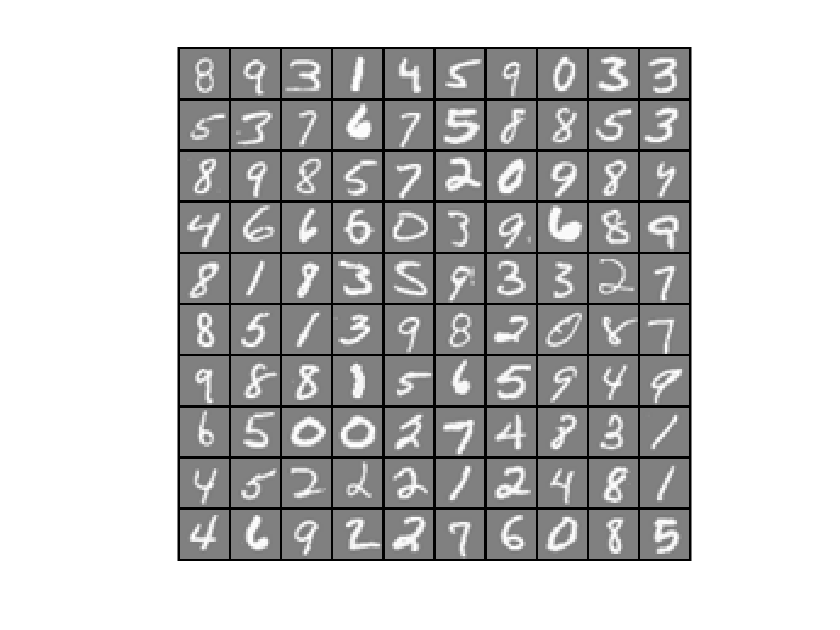

cd ('D:\Drive D\Siemens_DataBackup\Personal_Documents\Coursera\Machine_Learning\machine-learning-ex\ex4')
%Display data
load('ex4data1.mat');
m = size(X, 1);
% Randomly select 100 data points to display
sel = randperm(size(X, 1));
sel = sel(1:100);
displayData(X(sel, :));

%Already trained weights
% Load the weights into variables Theta1 and Theta2
load('ex4weights.mat');

Feedforward and cost function

input_layer_size  = 400;  % 20x20 Input Images of Digits
hidden_layer_size = 25;   % 25 hidden units
num_labels = 10;          % 10 labels, from 1 to 10 (note that we have mapped "0" to label 10)

% Unroll parameters 
nn_params = [Theta1(:) ; Theta2(:)];
% Weight regularization parameter (we set this to 0 here). Without
% Regualization 
lambda = 0;
J = nnCostFunction(nn_params, input_layer_size, hidden_layer_size, num_labels, X, y, lambda);
fprintf('Cost at parameters (loaded from ex4weights): %f', J);

Cost at parameters (loaded from ex4weights): 0.287629

Regularized cost function

% Weight regularization parameter (we set this to 1 here).
lambda = 1;
J = nnCostFunction(nn_params, input_layer_size, hidden_layer_size, num_labels, X, y, lambda);
fprintf('Cost at parameters (loaded from ex4weights): %f', J);

Cost at parameters (loaded from ex4weights): 0.383770

**Backpropagation**

Sigmoid gradient

% Call your sigmoidGradient function
sigmoidGradient(0)

ans = 0.2500

Random initialization for **symmetry breaking**

One effective strategy for random initialization is to randomly select values for $\Theta^{(l)}$ uniformly in the range $[-\epsilon_{int},\epsilon_{init}]$. You should use $\epsilon_{init} = 0.12$*. This range of values ensures that the parameters are kept small and makes the learning more efficient.

initial_Theta1 = randInitializeWeights(input_layer_size, hidden_layer_size);
initial_Theta2 = randInitializeWeights(hidden_layer_size, num_labels);

% Unroll parameters
initial_nn_params = [initial_Theta1(:) ; initial_Theta2(:)];

*One effective strategy for choosing $\epsilon_{init}$ is to base it on the number of units in the network. A good choice of $\epsilon_{init}$ is $\epsilon_{init} = \frac{\sqrt{6}}{\sqrt{L_{in}+L_{out}}},$ where $L_{in} = s_l$ and $L_{out} = s_{l+1}$ are the number of units in the layers adjacent to $\Theta^{(l)}$.

**Gradient checking **

Numerical Vs. Analytica Gradient check

checkNNGradients;

   -0.0093   -0.0093
    0.0089    0.0089
   -0.0084   -0.0084
    0.0076    0.0076
   -0.0067   -0.0067
   -0.0000   -0.0000
    0.0000    0.0000
   -0.0000   -0.0000
    0.0000    0.0000
   -0.0000   -0.0000
   -0.0002   -0.0002
    0.0002    0.0002
   -0.0003   -0.0003
    0.0003    0.0003
   -0.0004   -0.0004
   -0.0001   -0.0001
    0.0001    0.0001
   -0.0001   -0.0001
    0.0002    0.0002
   -0.0002   -0.0002
    0.3145    0.3145
    0.1111    0.1111
    0.0974    0.0974
    0.1641    0.1641
    0.0576    0.0576
    0.0505    0.0505
    0.1646    0.1646
    0.0578    0.0578
    0.0508    0.0508
    0.1583    0.1583
    0.0559    0.0559
    0.0492    0.0492
    0.1511    0.1511
    0.0537    0.0537
    0.0471    0.0471
    0.1496    0.1496
    0.0532    0.0532
    0.0466    0.0466

The above two columns you get should be very similar.
(Left-Your Numerical Gradient, Right-Analytical Gradient)

If your backpropagation implementation is correct, then 
the relative difference will be

**Regularized neural networks**

%  Check gradients by running checkNNGradients
lambda = 3;
checkNNGradients(lambda);

   -0.0093   -0.0093
    0.0089    0.0089
   -0.0084   -0.0084
    0.0076    0.0076
   -0.0067   -0.0067
   -0.0168   -0.0168
    0.0394    0.0394
    0.0593    0.0593
    0.0248    0.0248
   -0.0327   -0.0327
   -0.0602   -0.0602
   -0.0320   -0.0320
    0.0249    0.0249
    0.0598    0.0598
    0.0386    0.0386
   -0.0174   -0.0174
   -0.0576   -0.0576
   -0.0452   -0.0452
    0.0091    0.0091
    0.0546    0.0546
    0.3145    0.3145
    0.1111    0.1111
    0.0974    0.0974
    0.1187    0.1187
    0.0000    0.0000
    0.0337    0.0337
    0.2040    0.2040
    0.1171    0.1171
    0.0755    0.0755
    0.1257    0.1257
   -0.0041   -0.0041
    0.0170    0.0170
    0.1763    0.1763
    0.1131    0.1131
    0.0862    0.0862
    0.1323    0.1323
   -0.0045   -0.0045
    0.0015    0.0015

The above two columns you get should be very similar.
(Left-Your Numerical Gradient, Right-Analytical Gradient)

If your backpropagation implementation is correct, then 
the relative difference will be

% Also output the costFunction debugging value 
% This value should be about 0.576051
debug_J  = nnCostFunction(nn_params, input_layer_size, hidden_layer_size, num_labels, X, y, lambda);
fprintf('Cost at (fixed) debugging parameters (w/ lambda = 3): %f', debug_J);

Cost at (fixed) debugging parameters (w/ lambda = 3): 0.678580

**Learning parameters using **`fmincg`

options = optimset('MaxIter', 100); % Higher number of iterations would increase model accuracy
lambda = 1;

% Create "short hand" for the cost function to be minimized
costFunction = @(p) nnCostFunction(p, input_layer_size, hidden_layer_size, num_labels, X, y, lambda);

% Now, costFunction is a function that takes in only one argument (the
% neural network parameters)
[nn_params, ~] = fmincg(costFunction, initial_nn_params, options);

Iteration     1 | Cost: 3.521460e+00
Iteration     2 | Cost: 3.285123e+00
Iteration     3 | Cost: 3.144676e+00
Iteration     4 | Cost: 3.020945e+00
Iteration     5 | Cost: 2.912809e+00
Iteration     6 | Cost: 2.534949e+00
Iteration     7 | Cost: 2.169262e+00
Iteration     8 | Cost: 2.048561e+00
Iteration     9 | Cost: 1.889108e+00
Iteration    10 | Cost: 1.792895e+00
Iteration    11 | Cost: 1.657966e+00
Iteration    12 | Cost: 1.514542e+00
Iteration    13 | Cost: 1.464748e+00
Iteration    14 | Cost: 1.461505e+00
Iteration    15 | Cost: 1.344517e+00
Iteration    16 | Cost: 1.316244e+00
Iteration    17 | Cost: 1.277784e+00
Iteration    18 | Cost: 1.164132e+00
Iteration    19 | Cost: 9.782928e-01
Iteration    20 | Cost: 8.340280e-01
Iteration    21 | Cost: 7.890383e-01
Iteration    22 | Cost: 7.578289e-01
Iteration    23 | Cost: 7.285118e-01
Iteration    24 | Cost: 7.004258e-01
Iteration    25 | Cost: 6.870416e-01
Iteration    26 | Cost: 6.683771e-01
Iteration    27 | Cost: 6.541314e-01
I

Prediction and Accuracy

% Obtain Theta1 and Theta2 back from nn_params
Theta1 = reshape(nn_params(1:hidden_layer_size * (input_layer_size + 1)), hidden_layer_size, (input_layer_size + 1));
Theta2 = reshape(nn_params((1 + (hidden_layer_size * (input_layer_size + 1))):end), num_labels, (hidden_layer_size + 1));
 
pred = predict(Theta1, Theta2, X);
fprintf('\nTraining Set Accuracy: %f\n', mean(double(pred == y)) * 100);


Training Set Accuracy: 97.900000


Visualizing the hidden layer

% Visualize Weights 
displayData(Theta1(:, 2:end));

Impact of **learning rate** and **number of Max iteration** on Neural Network performance

% Change lambda and MaxIter to see how it affects the result
lambda = 3;
MaxIter = 150;
options = optimset('MaxIter', MaxIter);
% Create "short hand" for the cost function to be minimized
costFunction = @(p) nnCostFunction(p,input_layer_size, hidden_layer_size, num_labels, X, y, lambda);
% Now, costFunction is a function that takes in only one argument (the neural network parameters)
[nn_params, ~] = fmincg(costFunction, initial_nn_params, options);

Iteration     1 | Cost: 3.534415e+00
Iteration     2 | Cost: 3.298197e+00
Iteration     3 | Cost: 3.158722e+00
Iteration     4 | Cost: 3.036511e+00
Iteration     5 | Cost: 2.930454e+00
Iteration     6 | Cost: 2.561410e+00
Iteration     7 | Cost: 2.200096e+00
Iteration     8 | Cost: 2.084523e+00
Iteration     9 | Cost: 1.931841e+00
Iteration    10 | Cost: 1.839065e+00
Iteration    11 | Cost: 1.708674e+00
Iteration    12 | Cost: 1.571883e+00
Iteration    13 | Cost: 1.508127e+00
Iteration    14 | Cost: 1.370630e+00
Iteration    15 | Cost: 1.176194e+00
Iteration    16 | Cost: 1.133539e+00
Iteration    17 | Cost: 1.114844e+00
Iteration    18 | Cost: 1.072619e+00
Iteration    19 | Cost: 1.022976e+00
Iteration    20 | Cost: 9.825403e-01
Iteration    21 | Cost: 9.322632e-01
Iteration    22 | Cost: 9.030045e-01
Iteration    23 | Cost: 8.935970e-01
Iteration    24 | Cost: 8.651963e-01
Iteration    25 | Cost: 8.542320e-01
Iteration    26 | Cost: 8.413567e-01
Iteration    27 | Cost: 8.268318e-01
I


% Obtain Theta1 and Theta2 back from nn_params
Theta1 = reshape(nn_params(1:hidden_layer_size * (input_layer_size + 1)), hidden_layer_size, (input_layer_size + 1));
Theta2 = reshape(nn_params((1 + (hidden_layer_size * (input_layer_size + 1))):end), num_labels, (hidden_layer_size + 1));
 
pred = predict(Theta1, Theta2, X);
fprintf('\nTraining Set Accuracy: %f\n', mean(double(pred == y)) * 100);


Training Set Accuracy: 97.120000


Make prediction of random choice

% Randomly permute examples
%rp = randi(m);
% Display 
%displayData(X(rp, :)); 
% Predict
%pred = predict(Theta1, Theta2, X(rp,:));
%fprintf('\nNeural Network Prediction: %d (digit %d)\n', pred, mod(pred, 10));
% Trial from reading img
[X_try Y_try] = IMG('Nu4.jpg')

X_try =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Y_try = 5

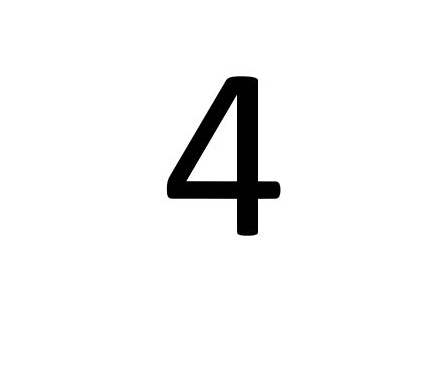

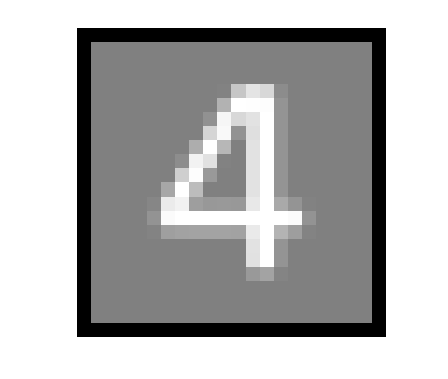

%[X_try, mu, sigma] = featureNormalize(X_try);
%X_try = X(1500,:);
%imshow(reshape(X_try,[20 20]))
displayData(X_try);

pred_try = predict(Theta1, Theta2, X_try);
fprintf('\nNeural Network Prediction: %d (digit %d)\n', pred_try, mod(pred_try, 10));


Neural Network Prediction: 9 (digit 9)
